# Image Captioning Using Attention

This example shows how to train a deep learning model for image captioning using attention.

Most pretrained deep learning networks are configured for single-label classification. For example, given an image of a typical office desk, the network might predict the single class "keyboard" or "mouse". In contrast, an image captioning model combines convolutional and recurrent operations to produce a textual description of what is in the image, rather than a single label.

This model trained in this example uses an encoder-decoder architecture. The encoder is a pretrained Inception-v3 network used as a feature extractor. The decoder is a recurrent neural network (RNN) that takes the extracted features as input and generates a caption. The decoder incorporates an *attention mechanism* that allows the decoder to focus on parts of the encoded input while generating the caption.

The encoder model is a pretrained Inception-v3 model that extracts features from the `"mixed10"` layer, followed by fully connected and ReLU operations.

The decoder model consists of a word embedding, an attention mechanism, a gated recurrent unit (GRU), and two fully connected operations.

## Load Pretrained Network

Load a pretrained Inception-v3 network. This step requires the Deep Learning Toolbox™ Model *for Inception-v3 Network* support package. If you do not have the required support package installed, then the software provides a download link.

net = inceptionv3;
inputSizeNet = net.Layers(1).InputSize;

Convert the network to a `dlnetwork` object for feature extraction and remove the last four layers, leaving the `"mixed10"` layer as the last layer.

lgraph = layerGraph(net);
lgraph = removeLayers(lgraph,["avg_pool" "predictions" "predictions_softmax" "ClassificationLayer_predictions"]);

View the input layer of the network. The Inception-v3 network uses symmetric-rescale normalization with a minimum value of 0 and a maximum value of 255.

lgraph.Layers(1)

ans =   ImageInputLayer - 属性:

                      Name: 'input_1'
                 InputSize: [299 299 3]

   超参数
          DataAugmentation: 'none'
             Normalization: 'rescale-symmetric'
    NormalizationDimension: 'auto'
                       Max: 255
                       Min: 0


Custom training does not support this normalization, so you must disable normalization in the network and perform the normalization in the custom training loop instead. Save the minimum and maximum values as doubles in variables named `inputMin` and `inputMax`, respectively, and replace the input layer with an image input layer without normalization.

inputMin = double(lgraph.Layers(1).Min);
inputMax = double(lgraph.Layers(1).Max);
layer = imageInputLayer(inputSizeNet,Normalization="none",Name="input");
lgraph = replaceLayer(lgraph,"input_1",layer);

Determine the output size of the network. Use the `analyzeNetwork` function to see the activation sizes of the last layer. To analyze the network for custom training loop workflows, set the `TargetUsage` option to `"dlnetwork"`.

analyzeNetwork(lgraph,TargetUsage="dlnetwork")

Create a variable named `outputSizeNet` containing the network output size.

outputSizeNet = [8 8 2048];

Convert the layer graph to a `dlnetwork` object and view the output layer. The output layer is the `"mixed10"` layer of the Inception-v3 network.

net = dlnetwork(lgraph)

net =   dlnetwork - 属性:

         Layers: [311×1 nnet.cnn.layer.Layer]
    Connections: [345×2 table]
     Learnables: [376×3 table]
          State: [188×3 table]
     InputNames: {'input'}
    OutputNames: {'mixed10'}
    Initialized: 1


## Import COCO Data Set

Download images and annotations from the data sets "2014 Train images" and "2014 Train/val annotations," respectively, from [https://cocodataset.org/#download](https://cocodataset.org/#download). Extract the images and annotations into a folder named `"coco"`.  The COCO 2014 data set was collected by [Coco Consortium](https://cocodataset.org).

Extract the captions from the file `"captions_train2014.json"` using the `jsondecode` function.

dataFolder = 'E:\Dataset\coco';

% dataFolder = fullfile("E:\Dataset\coco");
filename = fullfile(dataFolder,"annotations_trainval2014","annotations","captions_train2014.json");
str = fileread(filename);
data = jsondecode(str)

data = 包含以下字段的 struct :
           info: [1×1 struct]
         images: [82783×1 struct]
       licenses: [8×1 struct]
    annotations: [414113×1 struct]


The `annotations` field of the struct contains the data required for image captioning.

data.annotations

ans = 包含以下字段的 414113×1 struct 数组:
    image_id
    id
    caption


The data set contains multiple captions for each image. To ensure the same images do not appear in both training and validation sets, identify the unique images in the data set using the `unique` function by using the IDs in the `image_id` field of the annotations field of the data, then view the number of unique images.

numObservationsAll = numel(data.annotations)

numObservationsAll = 414113

imageIDs = [data.annotations.image_id];
imageIDsUnique = unique(imageIDs);
numUniqueImages = numel(imageIDsUnique)

numUniqueImages = 82783

Each image has at least five captions. Create a struct `annotationsAll` with these fields:

- `ImageID` ⁠— Image ID

- `Filename` ⁠— File name of the image

- `Captions` ⁠— String array of raw captions

- `CaptionIDs` ⁠— Vector of indices of the corresponding captions in `data.annotations`

To make merging easier, sort the annotations by the image IDs.

[~,idx] = sort([data.annotations.image_id]);
data.annotations = data.annotations(idx);

Loop over the annotations and merge multiple annotations when necessary.

## 循环注释并在必要时合并多个注释。

i = 0;
j = 0;
imageIDPrev = 0;
while i < numel(data.annotations)
    i = i + 1;
    
    imageID = data.annotations(i).image_id;
    caption = string(data.annotations(i).caption);
    
    if imageID ~= imageIDPrev
        % Create new entry
        j = j + 1;
        annotationsAll(j).ImageID = imageID;
        annotationsAll(j).Filename = fullfile(dataFolder,"train2014","COCO_train2014_" + pad(string(imageID),12,"left","0") + ".jpg");
        annotationsAll(j).Captions = caption;
        annotationsAll(j).CaptionIDs = i;
    else
        % Append captions
        annotationsAll(j).Captions = [annotationsAll(j).Captions; caption];
        annotationsAll(j).CaptionIDs = [annotationsAll(j).CaptionIDs; i];
    end
    
    imageIDPrev = imageID;
end

annotationsAll(1:5)

ans = 包含以下字段的 1×5 struct 数组:
    ImageID
    Filename
    Captions
    CaptionIDs


Partition the data into training and validation sets. Hold out 5% of the observations for testing.

## 将数据划分为训练集和验证集。 拿出 5% 的观察结果进行测试。

cvp = cvpartition(numel(annotationsAll),HoldOut=0.05);
idxTrain = training(cvp);
idxTest = test(cvp);
annotationsTrain = annotationsAll(idxTrain);
annotationsTest = annotationsAll(idxTest);

The struct contains three fields:

- `id `— Unique identifier for the caption

- `caption` — Image caption, specified as a character vector

- `image_id` — Unique identifier of the image corresponding to the caption

To view the image and the corresponding caption, locate the image file with file name `"train2014\COCO_train2014_XXXXXXXXXXXX.jpg"`, where `"XXXXXXXXXXXX"` corresponds to the image ID left-padded with zeros to have length 12.

imageID = annotationsTrain(2).ImageID;
captions = annotationsTrain(2).Captions;
filename = annotationsTrain(2).Filename;

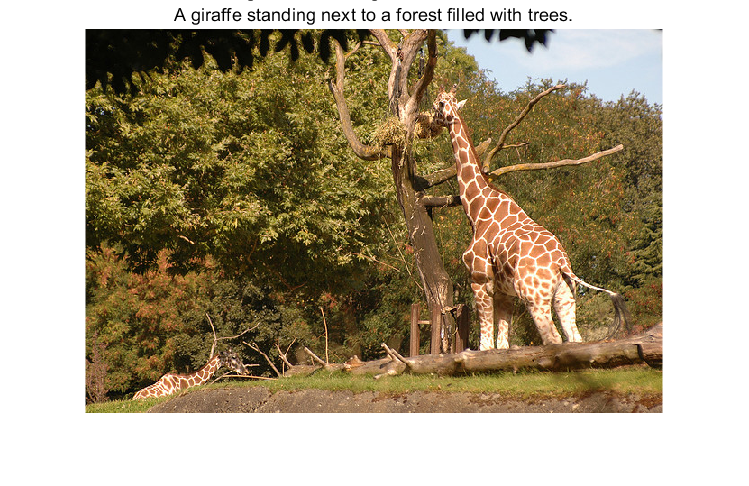

% 查看
img = imread(filename);
figure
imshow(img)
title(captions)

To view the image, use the `imread` and `imshow` functions.

## Prepare Data for Training

Prepare the captions for training and testing. Extract the text from the `Captions` field of the struct containing both the training and test data (`annotationsAll`), erase the punctuation, and convert the text to lowercase.

captionsAll = cat(1,annotationsAll.Captions);
captionsAll = erasePunctuation(captionsAll);
captionsAll = lower(captionsAll);

In order to generate captions, the RNN decoder requires special start and stop tokens to indicate when to start and stop generating text, respectively. Add the custom tokens `"<start>"` and `"<stop>"` to the beginnings and ends of the captions, respectively.

captionsAll = "<start>" + captionsAll + "<stop>";

Tokenize the captions using the `tokenizedDocument` function and specify the start and stop tokens using the `CustomTokens` option.

**使用 tokenizedDocument 函数标记字幕，并使用 CustomTokens 选项指定开始和停止标记。**

documentsAll = tokenizedDocument(captionsAll,CustomTokens=["<start>" "<stop>"]);

Create a `wordEncoding` object that maps words to numeric indices and back. Reduce the memory requirements by specifying a vocabulary size of 5000 corresponding to the most frequently observed words in the training data. To avoid bias, use only the documents corresponding to the training set.

**创建一个 wordEncoding 对象，将单词映射到数字索引并返回。 通过指定与训练数据中最常观察到的单词相对应的词汇量 5000 来减少内存需求。 为避免偏差，仅使用与训练集对应的文档。**

enc = wordEncoding(documentsAll(idxTrain),MaxNumWords=5000,Order="frequency");

Create an augmented image datastore containing the images corresponding to the captions. Set the output size to match the input size of the convolutional network. To keep the images synchronized with the captions, specify a table of file names for the datastore by reconstructing the file names using the image ID. To return grayscale images as 3-channel RGB images, set the `ColorPreprocessing` option to `"gray2rgb"`. 

**创建一个包含与字幕对应的图像的增强图像数据存储。 设置输出大小以匹配卷积网络的输入大小。 要使图像与标题保持同步，请通过使用图像 ID 重建文件名来为数据存储指定一个文件名表。 要将灰度图像作为 3 通道 RGB 图像返回，请将 ColorPreprocessing 选项设置为“gray2rgb”。**

tblFilenames = table(cat(1,annotationsTrain.Filename));
augimdsTrain = augmentedImageDatastore(inputSizeNet,tblFilenames,ColorPreprocessing="gray2rgb")

augimdsTrain =   augmentedImageDatastore - 属性:

         NumObservations: 78644
           MiniBatchSize: 1
        DataAugmentation: 'none'
      ColorPreprocessing: 'gray2rgb'
              OutputSize: [299 299]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


## Initialize Model Parameters

Initialize the model parameters. Specify 512 hidden units with a word embedding dimension of 256.

embeddingDimension = 256;
numHiddenUnits = 512;

Initialize a struct containing the parameters for the encoder model.

- Initialize the weights of the fully connected operations using the Glorot initializer, specified by the `initializeGlorot` function, listed at the end of the example. Specify the output size to match the embedding dimension of the decoder (256) and an input size to match the number of output channels of the pretrained network. The `'mixed10'` layer of the Inception-v3 network outputs data with 2048 channels.

numFeatures = outputSizeNet(1) * outputSizeNet(2);
inputSizeEncoder = outputSizeNet(3);
parametersEncoder = struct;

% Fully connect
parametersEncoder.fc.Weights = dlarray(initializeGlorot(embeddingDimension,inputSizeEncoder));
parametersEncoder.fc.Bias = dlarray(zeros([embeddingDimension 1],"single"));

Initialize a struct containing parameters for the decoder model.

- Initialize the word embedding weights with the size given by the embedding dimension and the vocabulary size plus one, where the extra entry corresponds to the padding value.

- Initialize the weights and biases for the Bahdanau attention mechanism with sizes corresponding to the number of hidden units of the GRU operation.

- Initialize the weights and bias of the GRU operation.

- Initialize the weights and biases of two fully connected operations.

For the model decoder parameters, initialize each of the weighs and biases with the Glorot initializer and zeros, respectively.

inputSizeDecoder = enc.NumWords + 1;
parametersDecoder = struct;

% Word embedding
parametersDecoder.emb.Weights = dlarray(initializeGlorot(embeddingDimension,inputSizeDecoder));

% Attention
parametersDecoder.attention.Weights1 = dlarray(initializeGlorot(numHiddenUnits,embeddingDimension));
parametersDecoder.attention.Bias1 = dlarray(zeros([numHiddenUnits 1],"single"));
parametersDecoder.attention.Weights2 = dlarray(initializeGlorot(numHiddenUnits,numHiddenUnits));
parametersDecoder.attention.Bias2 = dlarray(zeros([numHiddenUnits 1],"single"));
parametersDecoder.attention.WeightsV = dlarray(initializeGlorot(1,numHiddenUnits));
parametersDecoder.attention.BiasV = dlarray(zeros(1,1,"single"));

% GRU
parametersDecoder.gru.InputWeights = dlarray(initializeGlorot(3*numHiddenUnits,2*embeddingDimension));
parametersDecoder.gru.RecurrentWeights = dlarray(initializeGlorot(3*numHiddenUnits,numHiddenUnits));
parametersDecoder.gru.Bias = dlarray(zeros(3*numHiddenUnits,1,"single"));

% Fully connect
parametersDecoder.fc1.Weights = dlarray(initializeGlorot(numHiddenUnits,numHiddenUnits));
parametersDecoder.fc1.Bias = dlarray(zeros([numHiddenUnits 1],"single"));

% Fully connect
parametersDecoder.fc2.Weights = dlarray(initializeGlorot(enc.NumWords+1,numHiddenUnits));
parametersDecoder.fc2.Bias = dlarray(zeros([enc.NumWords+1 1],"single"));

## Define Model Functions

Create the functions `modelEncoder` and `modelDecoder`, listed at the end of the example, which compute the outputs of the encoder and decoder models, respectively.

The `modelEncoder` function, listed in the Encoder Model Function section of the example, takes as input an array of activations `X` from the output of the pretrained network and passes it through a fully connected operation and a ReLU operation. Because the pretrained network does not need to be traced for automatic differentiation, extracting the features outside the encoder model function is more computationally efficient. 

The `modelDecoder` function, listed in the Decoder Model Function section of the example, takes as input a single input time-step corresponding to an input word, the decoder model parameters, the features from the encoder, and the network state, and returns the predictions for the next time step, the updated network state, and the attention weights.

## Specify Training Options

Specify the options for training. Train for 30 epochs with a mini-batch size of 128 and display the training progress in a plot. 

miniBatchSize = 76;
numEpochs = 30;
plots = "training-progress";

Train on a GPU if one is available. Using a GPU requires Parallel Computing Toolbox™ and a supported GPU device. For information on supported devices, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f).

executionEnvironment = "gpu";

gpuDevice

ans =   CUDADevice - 属性:

                      Name: 'NVIDIA GeForce RTX 2060'
                     Index: 1
         ComputeCapability: '7.5'
            SupportsDouble: 1
             DriverVersion: 11.6000
            ToolkitVersion: 11.2000
        MaxThreadsPerBlock: 1024
          MaxShmemPerBlock: 49152
        MaxThreadBlockSize: [1024 1024 64]
               MaxGridSize: [2.1475e+09 65535 65535]
                 SIMDWidth: 32
               TotalMemory: 6.4420e+09
           AvailableMemory: 4.2745e+09
       MultiprocessorCount: 30
              ClockRateKHz: 1680000
               ComputeMode: 'Default'
      GPUOverlapsTransfers: 1
    KernelExecutionTimeout: 0
          CanMapHostMemory: 1
           DeviceSupported: 1
           DeviceAvailable: 1
            DeviceSelected: 1


## Train Network

Train the network using a custom training loop.

At the beginning of each epoch, shuffle the input data. To keep the images in the augmented image datastore and the captions synchronized, create an array of shuffled indices that indexes into both data sets.

For each mini-batch:

- Rescale the images to the size that the pretrained network expects.

- For each image, select a random caption.

- Convert the captions to sequences of word indices. Specify right-padding of the sequences with the padding value corresponding to the index of the padding token.

- Convert the data to `dlarray` objects. For the images, specify dimension labels `"SSCB"` (spatial, spatial, channel, batch).

- For GPU training, convert the data to `gpuArray` objects.

- Extract the image features using the pretrained network and reshape them to the size the encoder expects.

- Evaluate the model loss and gradients using the `dlfeval` and `modelLoss` functions.

- Update the encoder and decoder model parameters using the `adamupdate` function.

- Display the training progress in a plot.

Initialize the parameters for the Adam optimizer.

trailingAvgEncoder = [];
trailingAvgSqEncoder = [];

trailingAvgDecoder = [];
trailingAvgSqDecoder = [];

Initialize the training progress plot. Create an animated line that plots the loss against the corresponding iteration.

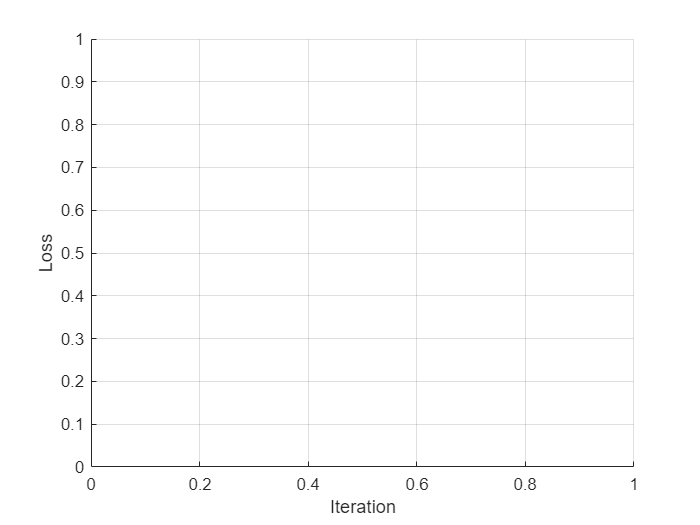

if plots == "training-progress"
    figure
    lineLossTrain = animatedline(Color=[0.85 0.325 0.098]);
    xlabel("Iteration")
    ylabel("Loss")
    ylim([0 inf])
    grid on
end

Train the model.

历时 3585.188673 秒。
历时 7152.772598 秒。
历时 10803.430547 秒。
历时 14391.831860 秒。
历时 17906.449077 秒。
历时 21252.303981 秒。
历时 24594.649813 秒。
历时 27916.569228 秒。
历时 31242.711587 秒。
历时 34576.720850 秒。
历时 37909.245822 秒。
历时 41241.318034 秒。
历时 44583.758053 秒。
历时 47954.730812 秒。
历时 51365.361738 秒。
历时 54958.903295 秒。
历时 58659.202555 秒。
历时 62312.758207 秒。
历时 66007.589209 秒。
历时 69564.446081 秒。
历时 73239.929221 秒。
历时 76771.716650 秒。
历时 80278.835163 秒。
历时 83735.989583 秒。
历时 87250.495260 秒。
历时 90791.424957 秒。
历时 94336.806786 秒。
历时 97794.060508 秒。
历时 101230.322722 秒。


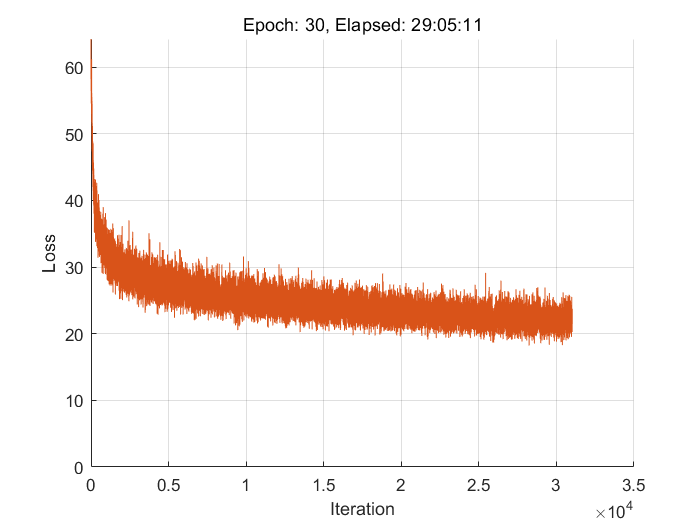

历时 104711.572284 秒。


iteration = 0;
numObservationsTrain = numel(annotationsTrain);
numIterationsPerEpoch = floor(numObservationsTrain / miniBatchSize);
start = tic;

% Loop over epochs.
tic

for epoch = 1:numEpochs
    
    % Shuffle data.
    idxShuffle = randperm(numObservationsTrain);
    
    % Loop over mini-batches.
    for i = 1:numIterationsPerEpoch
        iteration = iteration + 1;
        
        % Determine mini-batch indices.
        idx = (i-1)*miniBatchSize+1:i*miniBatchSize;
        idxMiniBatch = idxShuffle(idx);
        
        % Read mini-batch of data.
        tbl = readByIndex(augimdsTrain,idxMiniBatch);
        X = cat(4,tbl.input{:});
        annotations = annotationsTrain(idxMiniBatch);
        
        % For each image, select random caption.
        idx = cellfun(@(captionIDs) randsample(captionIDs,1),{annotations.CaptionIDs});
        documents = documentsAll(idx);
        
        % Create batch of data.
        [X, T] = createBatch(X,documents,net,inputMin,inputMax,enc,executionEnvironment);
        
        % Evaluate the model loss and gradients using dlfeval and the
        % modelLoss function.
        [loss, gradientsEncoder, gradientsDecoder] = dlfeval(@modelLoss, parametersEncoder, ...
            parametersDecoder, X, T);
        
        % Update encoder using adamupdate.
        [parametersEncoder, trailingAvgEncoder, trailingAvgSqEncoder] = adamupdate(parametersEncoder, ...
            gradientsEncoder, trailingAvgEncoder, trailingAvgSqEncoder, iteration);
        
        % Update decoder using adamupdate.
        [parametersDecoder, trailingAvgDecoder, trailingAvgSqDecoder] = adamupdate(parametersDecoder, ...
            gradientsDecoder, trailingAvgDecoder, trailingAvgSqDecoder, iteration);
        
        % Display the training progress.
        if plots == "training-progress"
            D = duration(0,0,toc(start),Format="hh:mm:ss");
            addpoints(lineLossTrain,iteration,double(loss))
            title("Epoch: " + epoch + ", Elapsed: " + string(D))
            
            drawnow
        end   
    end
toc
end

## Predict New Captions

The caption generation process is different from the process for training. During training, at each time step, the decoder uses the true value of the previous time step as input. This is known as "teacher forcing". When making predictions on new data, the decoder uses the previous predicted values instead of the true values.

Predicting the most likely word for each step in the sequence can lead to suboptimal results. For example, if the decoder predicts the first word of a caption is "a" when given an image of an elephant, then the probability of predicting "elephant" for the next word becomes much more unlikely because of the extremely low probability of the phrase "a elephant" appearing in English text.

To address this issue, you can use the beam search algorithm: instead of taking the most likely prediction for each step in the sequence, take the top *k* predictions (the beam index) and for each following step, keep the top *k* predicted sequences so far according to the overall score.

Generate a caption of a new image by extracting the image features, inputting them into the encoder, and then using the `beamSearch` function, listed in the Beam Search Function section of the example.

img = imread("laika_sitting.jpg");

## 读取数据集并进行视觉语言推理

ds = imageDatastore( ...
    ['E:\SHAPClab_UrbanPerception_StreetAccessibility-main' ...
    '\Streetview_Download\save_joint_images\JNU\*.jpg']);
ds.Files

long = length(ds.Files)

long = 200

ans = 1112×1 cell 数组
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\1.jpg'   }
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\10.jpg'  }
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\100.jpg' }
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\1000.jpg'}
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\1001.jpg'}
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\1002.jpg'}
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\1003.jpg'}
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\1004.jpg'}
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save

caption = [];

long = 1112

bar = waitbar(0,'读取数据中...')
tic

long = 200

for i = 1:long
    X = extractImageFeatures(net,readimage(ds,i),inputMin,inputMax,executionEnvironment);


bar =   Figure (TMWWaitbar) - 属性:

      Number: []
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [633 403.8750 270 56.2500]
       Units: 'points'

  显示 所有属性


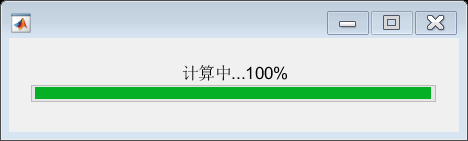

    beamIndex = 2;
    maxNumWords = 20;
    words = beamSearch(X,beamIndex,parametersEncoder,parametersDecoder,enc,maxNumWords);
    caption = [caption;join(words)];

    str = ['计算中...',num2str(i/long*100),'%'];
    waitbar(i/long*100,bar,str)
    clc
end
toc

caption

历时 377.174608 秒。


P = cellstr([ds.Files(1:long),caption])

caption = 1112×1 string 数组
    "a bridge crosses a river with a city in the background with trees in the background and a group"
    "a view of a river with a boat in the background with trees in the background and trees in"
    "a group of people standing in front of a large body of water with umbrellas in the background on"
    "a river with a lot of trees and a clock on the side of the road with trees in"
    "a group of people riding skis on top of a snow covered forest"
    "a group of people standing on top of a cement surface overlooking a green field with a sailboat in"
    "a group of people standing on top of a bridge"
    "a couple of umbrellas that are sitting in the water"
    "a boat sitting on the side of a river with a large fountain in the background with tall trees"
    "a picture of a makeshift toilet in a wooded area with a large tree in the background"
    "a group of people walking down a path near a forest"
    "a person riding a skate board at a skate park in th

cell2csv('E:\Dataset\school image\final data\JNU_annotation3.csv',P)

P = 1112×2 cell 数组
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\1.jpg'   }    {'a bridge crosses a river with a city in the background with trees in the background and a group'   }
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\10.jpg'  }    {'a view of a river with a boat in the background with trees in the background and trees in'         }
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\100.jpg' }    {'a group of people standing in front of a large body of water with umbrellas in the background on'  }
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\1000.jpg'}    {'a river with a lot of trees and a clock on the side of the road with trees in'                     }
    {'E:\SHAPClab_UrbanPerception_StreetAccessibility-main\Streetview_Download\save_joint_images\JNU\1001.jpg

## 单张图像推理示例

X = extractImageFeatures(net,img,inputMin,inputMax,executionEnvironment);

beamIndex = 3;
maxNumWords = 20;
[words,attentionScores] = beamSearch(X,beamIndex,parametersEncoder,parametersDecoder,enc,maxNumWords);
caption = join(words)

Display the image with the caption.

figure
imshow(img)
title(caption)

img2 = imread('E:\test.jpg')

caption = "a dog is sitting on a chair in front of a coffee table with a bear behind him outside"

attentionScores =   64×20 single gpuArray dlarray

    0.0339    0.0217    0.0226    0.0110    0.0155    0.0144    0.0107    0.0121    0.0114    0.0246    0.0193    0.0182    0.0154    0.0092    0.0079    0.0051    0.0071    0.0055    0.0122    0.0078
    0.0131    0.0055    0.0015    0.0002    0.0003    0.0002    0.0003    0.0006    0.0001    0.0003    0.0003    0.0006    0.0003    0.0003    0.0002    0.0002    0.0002    0.0001    0.0001    0.0001
    0.0168    0.0036    0.0020    0.0005    0.0008    0.0007    0.0011    0.0011    0.0003    0.0008    0.0004    0.0011    0.0004    0.0005    0.0003    0.0003    0.0004    0.0001    0.0001    0.0001
    0.0205    0.0073    0.0026    0.0007    0.0011    0.0009    0.0020    0.0010    0.0003    0.0016    0.0008    0.0014    0.0006    0.0008    0.0007    

imshow(img2)

X = extractImageFeatures(net,img2,inputMin,inputMax,executionEnvironment);

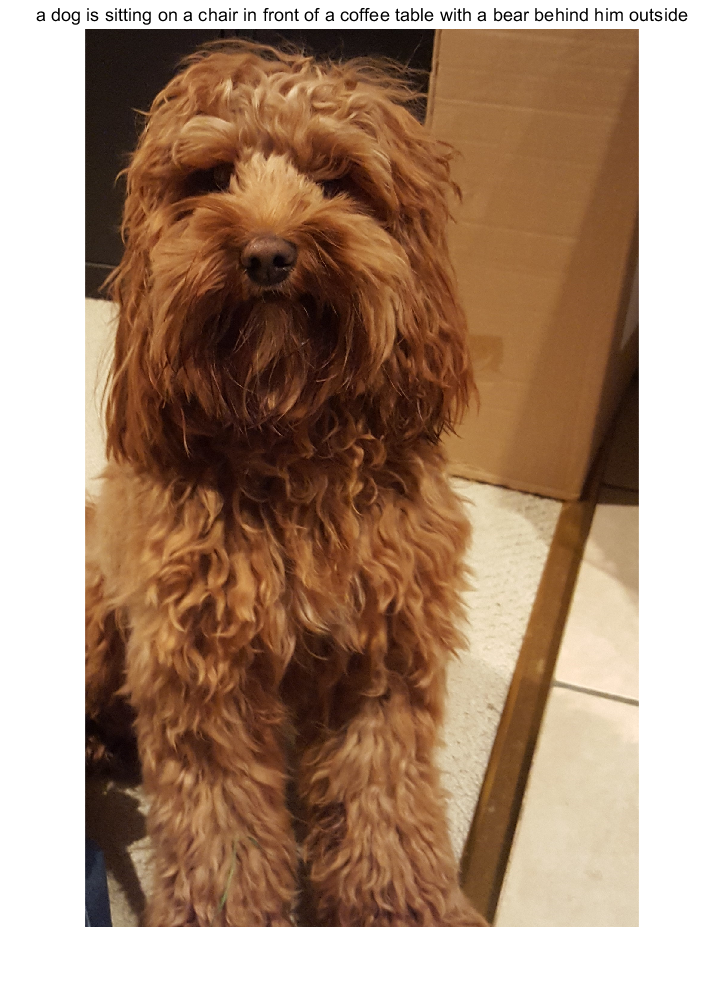

beamIndex = 3;
maxNumWords = 20;

[words,attentionScores] = beamSearch(X,beamIndex,parametersEncoder,parametersDecoder,enc,maxNumWords);
caption = join(words)

img2 = 600×900×3 uint8 数组
img2(:,:,1) =

   121   149   192   213   204   199   197   193   189   191   193   189   192   195   190   188   196   193   183   191   200   201   190   171   185   202   208   223   196   201   183   155   125   148   167   143   158   182   172   168   146   113   136   196   170   144   123   120   124   120   144   140   144   153   124   132   166   192   187   182    80    50   150   208   157    94    69    50    59   128   187   208   195   184   188   186   181   185   179   160   192   202   207   128    71   147   195   191   189   187   187   187   187   188   186   186   186   186   186   186   186   186   186   186   186   186   186   186   186   186   186   186   186   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   187   188   188   188   188   188   188   188   188   188   187   188   188   188   188   188   188   188   188   188   188   188   188   188   189   189   189   189   189   189   18

## Predict Captions for Data Set

To predict captions for a collection of images, loop over mini-batches of data in the datastore and extract the features from the images using the `extractImageFeatures` function. Then, loop over the images in the mini-batch and generate captions using the `beamSearch` function. 

Create an augmented image datastore and set the output size to match the input size of the convolutional network. To output grayscale images as 3-channel RGB images, set the `ColorPreprocessing` option to `"gray2rgb"`. 

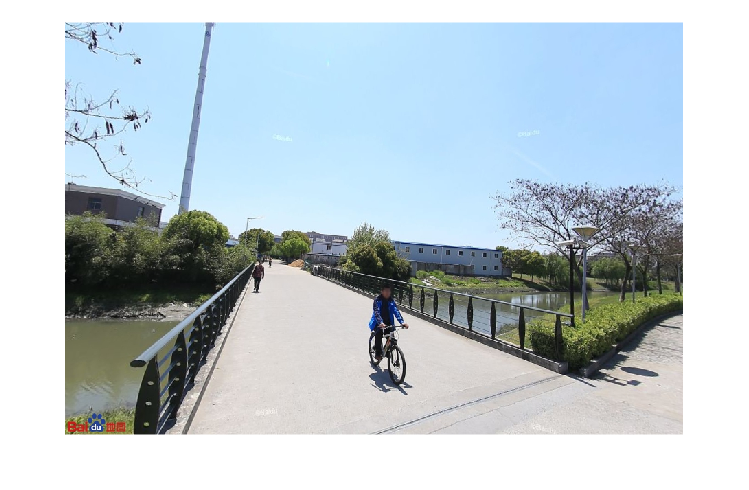

tblFilenamesTest = table(cat(1,annotationsTest.Filename));

augimdsTest = augmentedImageDatastore(inputSizeNet,tblFilenamesTest,ColorPreprocessing="gray2rgb")

Generate captions for the test data. Predicting captions on a large data set can take some time. If you have Parallel Computing Toolbox™, then you can make predictions in parallel by generating captions inside a `parfor` look. If you do not have Parallel Computing Toolbox. then the `parfor` loop runs in serial.

miniBatchSize = 16;

a = 64×2048 single 矩阵
    0.0531    0.2027    0.8174         0         0         0    0.2304    0.4401         0    1.2501         0         0         0         0    0.4400         0    0.1211         0         0         0    1.6676         0    0.2109         0    0.7311    0.5934         0    1.1638    0.7835    2.3836    0.1974    0.7398    0.3362         0         0    0.2053         0    0.0845    1.8574    0.4372         0    0.1531         0    0.5074         0    0.2192         0    1.5960         0    0.7431
    0.0180    0.5523    0.6078         0         0         0    0.1562    0.6785         0    0.4957    0.6434    0.2180         0         0         0    0.8971    0.1029         0         0    0.2955    2.1755         0    0.8514    0.1440    0.8840    1.2487         0         0    1.6541    3.5608    0.2055    0.1972    0.2621         0    0.8970    0.4042    0.5377         0    2.7288         0    0.9122    0.2719         0    1.0317    0.1033    0.9074    0.0131    0.4

beamIndex = 2;
maxNumWords = 20;

numObservationsTest = numel(annotationsTest);

caption = "a man riding a bike down a street next to a park"

numIterationsTest = ceil(numObservationsTest/miniBatchSize);

captionsTestPred = strings(1,numObservationsTest);
documentsTestPred = tokenizedDocument(strings(1,numObservationsTest));

for i = 1:numIterationsTest

augimdsTest =   augmentedImageDatastore - 属性:

         NumObservations: 4139
           MiniBatchSize: 1
        DataAugmentation: 'none'
      ColorPreprocessing: 'gray2rgb'
              OutputSize: [299 299]
          OutputSizeMode: 'resize'
    DispatchInBackground: 0


    % Mini-batch indices.
    idxStart = (i-1)*miniBatchSize+1;
    idxEnd = min(i*miniBatchSize,numObservationsTest);
    idx = idxStart:idxEnd;
    
    sz = numel(idx);
    
    % Read images.
    tbl = readByIndex(augimdsTest,idx);
    
    % Extract image features.
    X = cat(4,tbl.input{:});
    X = extractImageFeatures(net,X,inputMin,inputMax,executionEnvironment);
    
    % Generate captions.
    captionsPredMiniBatch = strings(1,sz);
    documentsPredMiniBatch = tokenizedDocument(strings(1,sz));
    
    parfor j = 1:sz
        words = beamSearch(X(:,:,j),beamIndex,parametersEncoder,parametersDecoder,enc,maxNumWords);
        captionsPredMiniBatch(j) = join(words);
        documentsPredMiniBatch(j) = tokenizedDocument(words,TokenizeMethod="none");
    end
    
    captionsTestPred(idx) = captionsPredMiniBatch;
    documentsTestPred(idx) = documentsPredMiniBatch;
end

Starting parallel pool (parpool) using the 'local' profile ...
Preserving jobs with IDs: 1 2 because they contain crash dump files.
You can use 'delete(myCluster.Jobs)' to remove all jobs created with profile local. To create 'myCluster' use 'myCluster = parcluster('local')'.
Connected to the parallel pool (number of workers: 6).
警告: Unable to load gpuArray data onto a GPU. Computations cannot be performed on this limited gpuArray. Use GATHER to retrieve the contents.
> 位置：parallel.internal.pool.deserialize (第 33 行)
位置: 

Array construction from ByteBuffer Threw an exception.

To view a test image with the corresponding caption, use the `imshow` function and set the title to the predicted caption.

## Evaluate Model Accuracy

To evaluate the accuracy of the captions using the BLEU score, calculate the BLEU score for each caption (the candidate) against the corresponding captions in the test set (the references) using the `bleuEvaluationScore` function. Using the `bleuEvaluationScore` function, you can compare a single candidate document to multiple reference documents.

The `bleuEvaluationScore` function, by default, scores similarity using n-grams of length one through four. As the captions are short, this behavior can lead to uninformative results as most scores are close to zero. Set the n-gram length to one through two by setting the `NgramWeights` option to a two-element vector with equal weights.

ngramWeights = [0.5 0.5];

for i = 1:numObservationsTest
    annotation = annotationsTest(i);
    
    captionIDs = annotation.CaptionIDs;
    candidate = documentsTestPred(i);
    references = documentsAll(captionIDs);
    
    score = bleuEvaluationScore(candidate,references,NgramWeights=ngramWeights);
    
    scores(i) = score;
end

View the mean BLEU score.

scoreMean = mean(scores)

Visualize the scores in a histogram.

figure
histogram(scores)
xlabel("BLEU Score")
ylabel("Frequency")

function cell2csv(fileName, cellArray, separator, excelYear, decimal)
% Writes cell array content into a *.csv file.
% 
% CELL2CSV(fileName, cellArray, separator, excelYear, decimal)
%
% fileName     = Name of the file to save. [ i.e. 'text.csv' ]
% cellArray    = Name of the Cell Array where the data is in
% separator    = sign separating the values (default = ';')
% excelYear    = depending on the Excel version, the cells are put into
%                quotes before they are written to the file. The separator
%                is set to semicolon (;)
% decimal      = defines the decimal separator (default = '.')
%
%         by Sylvain Fiedler, KA, 2004
% updated by Sylvain Fiedler, Metz, 06
% fixed the logical-bug, Kaiserslautern, 06/2008, S.Fiedler
% added the choice of decimal separator, 11/2010, S.Fiedler
%% Checking f黵 optional Variables
if ~exist('separator', 'var')
    separator = ',';
end
if ~exist('excelYear', 'var')
    excelYear = 1997;
end
if ~exist('decimal', 'var')
    decimal = '.';
end
%% Setting separator for newer excelYears
if excelYear > 2000
    separator = ';';
end
%% Write file
datei = fopen(fileName, 'w');
for z=1:size(cellArray, 1)
    for s=1:size(cellArray, 2)
        var = eval(['cellArray{z,s}']);
        % If zero, then empty cell
        if size(var, 1) == 0
            var = '';
        end
        % If numeric -> String
        if isnumeric(var)
            var = num2str(var);
            % Conversion of decimal separator (4 Europe & South America)
            % http://commons.wikimedia.org/wiki/File:DecimalSeparator.svg
            if decimal ~= '.'
                var = strrep(var, '.', decimal);
            end
        end
        % If logical -> 'true' or 'false'
        if islogical(var)
            if var == 1
                var = 'TRUE';
            else
                var = 'FALSE';
            end
        end
        % If newer version of Excel -> Quotes 4 Strings
        if excelYear > 2000
            var = ['"' var '"'];
        end
        % OUTPUT value
        fprintf(datei, '%s', var);
        % OUTPUT separator
        if s ~= size(cellArray, 2)
            fprintf(datei, separator);
        end
    end
    if z ~= size(cellArray, 1) % prevent a empty line at EOF
        % OUTPUT newline
        fprintf(datei, '\n');
    end
end
% Closing file
fclose(datei);
% END
end

## Attention Function

The `attention` function calculates the context vector and the attention weights using Bahdanau attention.

function [contextVector, attentionWeights] = attention(hidden,features,weights1, ...
    bias1,weights2,bias2,weightsV,biasV)

% Model dimensions.
[embeddingDimension,numFeatures,miniBatchSize] = size(features);
numHiddenUnits = size(weights1,1);

% Fully connect.
Y1 = reshape(features,embeddingDimension, numFeatures*miniBatchSize);
Y1 = fullyconnect(Y1,weights1,bias1,DataFormat="CB");
Y1 = reshape(Y1,numHiddenUnits,numFeatures,miniBatchSize);

% Fully connect.
Y2 = fullyconnect(hidden,weights2,bias2,DataFormat="CB");
Y2 = reshape(Y2,numHiddenUnits,1,miniBatchSize);

% Addition, tanh.
scores = tanh(Y1 + Y2);
scores = reshape(scores, numHiddenUnits, numFeatures*miniBatchSize);

% Fully connect, softmax.
attentionWeights = fullyconnect(scores,weightsV,biasV,DataFormat="CB");
attentionWeights = reshape(attentionWeights,1,numFeatures,miniBatchSize);
attentionWeights = softmax(attentionWeights,DataFormat="SCB");

% Context.
contextVector = attentionWeights .* features;
contextVector = squeeze(sum(contextVector,2));

end

## Embedding Function

The `embedding` function maps an array of indices to a sequence of embedding vectors.

function Z = embedding(X, weights)

% Reshape inputs into a vector
[N, T] = size(X, 1:2);
X = reshape(X, N*T, 1);

% Index into embedding matrix
Z = weights(:, X);

% Reshape outputs by separating out batch and sequence dimensions
Z = reshape(Z, [], N, T);

end

## Feature Extraction Function

The `extractImageFeatures` function takes as input a trained `dlnetwork` object, an input image, statistics for image rescaling, and the execution environment, and returns a `dlarray` containing the features extracted from the pretrained network.

function X = extractImageFeatures(net,X,inputMin,inputMax,executionEnvironment)

% Resize and rescale.
inputSize = net.Layers(1).InputSize(1:2);
X = imresize(X,inputSize);
X = rescale(X,-1,1,InputMin=inputMin,InputMax=inputMax);

% Convert to dlarray.
X = dlarray(X,"SSCB");

% Convert to gpuArray.
if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    X = gpuArray(X);
end

% Extract features and reshape.
X = predict(net,X);
sz = size(X);
numFeatures = sz(1) * sz(2);
inputSizeEncoder = sz(3);
miniBatchSize = sz(4);
X = reshape(X,[numFeatures inputSizeEncoder miniBatchSize]);

end

## Batch Creation Function

The `createBatch` function takes as input a mini-batch of data, tokenized captions, a pretrained network, statistics for image rescaling, a word encoding, and the execution environment, and returns a mini-batch of data corresponding to the extracted image features and captions for training.

function [X, T] = createBatch(X,documents,net,inputMin,inputMax,enc,executionEnvironment)

X = extractImageFeatures(net,X,inputMin,inputMax,executionEnvironment);

% Convert documents to sequences of word indices.
T = doc2sequence(enc,documents,PaddingDirection="right",PaddingValue=enc.NumWords+1);
T = cat(1,T{:});

% Convert mini-batch of data to dlarray.
T = dlarray(T);

% If training on a GPU, then convert data to gpuArray.
if (executionEnvironment == "auto" && canUseGPU) || executionEnvironment == "gpu"
    T = gpuArray(T);
end

end

## Encoder Model Function

The `modelEncoder` function takes as input an array of activations `X` and passes it through a fully connected operation and a ReLU operation. For the fully connected operation, operate on the channel dimension only. To apply the fully connected operation across the channel dimension only, flatten the other channels into a single dimension and specify this dimension as the batch dimension using the `DataFormat` option of the `fullyconnect` function.

function Y = modelEncoder(X,parametersEncoder)

[numFeatures,inputSizeEncoder,miniBatchSize] = size(X);

% Fully connect
weights = parametersEncoder.fc.Weights;
bias = parametersEncoder.fc.Bias;
embeddingDimension = size(weights,1);

X = permute(X,[2 1 3]);
X = reshape(X,inputSizeEncoder,numFeatures*miniBatchSize);
Y = fullyconnect(X,weights,bias,DataFormat="CB");
Y = reshape(Y,embeddingDimension,numFeatures,miniBatchSize);

% ReLU
Y = relu(Y);

end

## Decoder Model Function

The `modelDecoder` function takes as input a single time-step `X`, the decoder model parameters, the features from the encoder, and the network state, and returns the predictions for the next time step, the updated network state, and the attention weights.

function [Y,state,attentionWeights] = modelDecoder(X,parametersDecoder,features,state)

hiddenState = state.gru.HiddenState;

% Attention
weights1 = parametersDecoder.attention.Weights1;
bias1 = parametersDecoder.attention.Bias1;
weights2 = parametersDecoder.attention.Weights2;
bias2 = parametersDecoder.attention.Bias2;
weightsV = parametersDecoder.attention.WeightsV;
biasV = parametersDecoder.attention.BiasV;
[contextVector, attentionWeights] = attention(hiddenState,features,weights1,bias1,weights2,bias2,weightsV,biasV);

% Embedding
weights = parametersDecoder.emb.Weights;
X = embedding(X,weights);

% Concatenate
Y = cat(1,contextVector,X);

% GRU
inputWeights = parametersDecoder.gru.InputWeights;
recurrentWeights = parametersDecoder.gru.RecurrentWeights;
bias = parametersDecoder.gru.Bias;
[Y, hiddenState] = gru(Y, hiddenState, inputWeights, recurrentWeights, bias, DataFormat="CBT");

% Update state
state.gru.HiddenState = hiddenState;

% Fully connect
weights = parametersDecoder.fc1.Weights;
bias = parametersDecoder.fc1.Bias;
Y = fullyconnect(Y,weights,bias,DataFormat="CB");

% Fully connect
weights = parametersDecoder.fc2.Weights;
bias = parametersDecoder.fc2.Bias;
Y = fullyconnect(Y,weights,bias,DataFormat="CB");

end

## Model Loss

The `modelLoss` function takes as input the encoder and decoder parameters, the encoder features `X`, and the target caption `T`, and returns the loss, the gradients of the encoder and decoder parameters with respect to the loss, and the predictions.

function [loss,gradientsEncoder,gradientsDecoder,YPred] = ...
    modelLoss(parametersEncoder,parametersDecoder,X,T)

miniBatchSize = size(X,3);
sequenceLength = size(T,2) - 1;
vocabSize = size(parametersDecoder.emb.Weights,2);

% Model encoder
features = modelEncoder(X,parametersEncoder);

% Initialize state
numHiddenUnits = size(parametersDecoder.attention.Weights1,1);
state = struct;
state.gru.HiddenState = dlarray(zeros([numHiddenUnits miniBatchSize],"single"));

YPred = dlarray(zeros([vocabSize miniBatchSize sequenceLength],"like",X));
loss = dlarray(single(0));

padToken = vocabSize;

for t = 1:sequenceLength
    decoderInput = T(:,t);
    
    YReal = T(:,t+1);
    
    [YPred(:,:,t),state] = modelDecoder(decoderInput,parametersDecoder,features,state);
    
    mask = YReal ~= padToken;
    
    loss = loss + sparseCrossEntropyAndSoftmax(YPred(:,:,t),YReal,mask);
end

% Calculate gradients
[gradientsEncoder,gradientsDecoder] = dlgradient(loss, parametersEncoder,parametersDecoder);

end

## Sparse Cross Entropy and Softmax Loss Function

The `sparseCrossEntropyAndSoftmax` takes as input the predictions `Y`, corresponding targets `T`, and sequence padding mask, and applies the `softmax` functions and returns the cross-entropy loss.

function loss = sparseCrossEntropyAndSoftmax(Y, T, mask)

miniBatchSize = size(Y, 2);

% Softmax.
Y = softmax(Y,DataFormat="CB");

% Find rows corresponding to the target words.
idx = sub2ind(size(Y), T', 1:miniBatchSize);
Y = Y(idx);

% Bound away from zero.
Y = max(Y, single(1e-8));

% Masked loss.
loss = log(Y) .* mask';
loss = -sum(loss,"all") ./ miniBatchSize;

end

## Beam Search Function

The `beamSearch` function takes as input the image features `X`, a beam index, the parameters for the encoder and decoder networks, a word encoding, and a maximum sequence length, and returns the caption words for the image using the beam search algorithm.

function [words,attentionScores] = beamSearch(X,beamIndex,parametersEncoder,parametersDecoder, ...
    enc,maxNumWords)

% Model dimensions
numFeatures = size(X,1);
numHiddenUnits = size(parametersDecoder.attention.Weights1,1);

% Extract features
features = modelEncoder(X,parametersEncoder);

% Initialize state
state = struct;
state.gru.HiddenState = dlarray(zeros([numHiddenUnits 1],"like",X));

% Initialize candidates
candidates = struct;
candidates.State = state;
candidates.Words = "<start>";
candidates.Score = 0;
candidates.AttentionScores = dlarray(zeros([numFeatures maxNumWords],"like",X));
candidates.StopFlag = false;

t = 0;

% Loop over words
while t < maxNumWords
    t = t + 1;
    
    candidatesNew = [];
    
    % Loop over candidates
    for i = 1:numel(candidates)
        
        % Stop generating when stop token is predicted
        if candidates(i).StopFlag
            continue
        end
        
        % Candidate details
        state = candidates(i).State;
        words = candidates(i).Words;
        score = candidates(i).Score;
        attentionScores = candidates(i).AttentionScores;
        
        % Predict next token
        decoderInput = word2ind(enc,words(end));
        [YPred,state,attentionScores(:,t)] = modelDecoder(decoderInput,parametersDecoder,features,state);
        
        YPred = softmax(YPred,DataFormat="CB");
        [scoresTop,idxTop] = maxk(extractdata(YPred),beamIndex);
        idxTop = gather(idxTop);
        
        % Loop over top predictions
        for j = 1:beamIndex
            candidate = struct;
            
            candidateWord = ind2word(enc,idxTop(j));
            candidateScore = scoresTop(j);
            
            if candidateWord == "<stop>"
                candidate.StopFlag = true;
                attentionScores(:,t+1:end) = [];
            else
                candidate.StopFlag = false;
            end
            
            candidate.State = state;
            candidate.Words = [words candidateWord];
            candidate.Score = score + log(candidateScore);
            candidate.AttentionScores = attentionScores;
            
            candidatesNew = [candidatesNew candidate];
        end
    end
    
    % Get top candidates
    [~,idx] = maxk([candidatesNew.Score],beamIndex);
    candidates = candidatesNew(idx);
    
    % Stop predicting when all candidates have stop token
    if all([candidates.StopFlag])
        break
    end
end

% Get top candidate
words = candidates(1).Words(2:end-1);
attentionScores = candidates(1).AttentionScores;

end

## Glorot Weight Initialization Function

The `initializeGlorot` function generates an array of weights according to Glorot initialization.

function weights = initializeGlorot(numOut, numIn)

varWeights = sqrt( 6 / (numIn + numOut) );
weights = varWeights * (2 * rand([numOut, numIn], "single") - 1);

end

Copyright 2019 The MathWorks, Inc.